leading = readtable("E:\lhsPrograms\Projects_2020\OrbitForward0921\forward\SUM_0921_M1_7cm\Guidao-1\output\A-report_60L_M2.txt");
tracing = readtable("E:\lhsPrograms\Projects_2020\OrbitForward0921\forward\SUM_0921_M1_7cm\Guidao-2\output\A-report_60L_M2.txt");

leading = leading(1: 6000030, :);

leading = 6000030×7 table
          Var1                Var2                Var3                Var4                Var5                Var6                Var7       
    ________________    ________________    ________________    ________________    ________________    ________________    _________________

           2455958.5    792052.156696306    881056.346022935    6723167.96912054    4401.17874438592    6101.88667293277    -1306.10551736962
    2455958.50000116     792492.26963601    881666.529159668    6723037.31656332    4401.08004057075    6101.77604906788    -1306.94562428264
    2455958.50000231    792932.372702594    882276.701230216    6722906.57999624     4400.9812819729    6101.66534922056    -1307.78571437245
    2455958.50000347    7

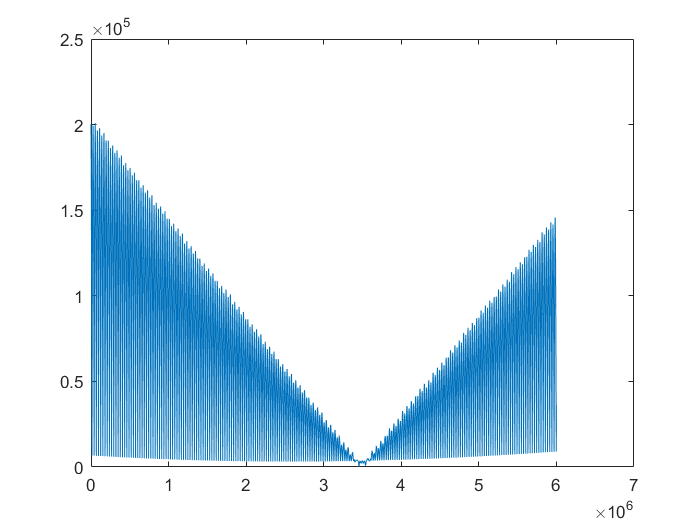

distance = zeros(height(tracing), 1);
for i = 1: height(tracing)
    distance(i) = sqrt((leading.Var1(i) - tracing.Var1(i))^2 + (leading.Var2(i) - tracing.Var2(i))^2 + (leading.Var3(i) - tracing.Var3(i))^2);
end
plot(distance)